clc;clear all;close all;
A=[0 0 1 0;
   0 0 0 1;
   0 149.3 -0.0104 0;
   0 261.6 -0.0103 0];
B=[0;0; 49.73; 49.15];
C=[1 0 0 0];
D=0;
Q1=diag([10 1 1 1])

Q1 =     10     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Q2=diag([1000 1 1 1])

Q2 =         1000           0           0           0
           0           1           0           0
           0           0           1           0
           0           0           0           1


R=0.01;

K1=lqr(A,B,Q1,R)

K1 =   -31.6228  320.3636  -16.5133   31.3404


K2=lqr(A,B,Q2,R)

K2 =  -316.2278  938.2384  -72.2047   88.1407


Kr1 = -31.6228

Kr1=inv(-(C-D*K1)*(A-B*K1)^-1*B+D)
Kr2=inv(-(C-D*K2)*(A-B*K2)^-1*B+D)

Kr2 = -316.2278


ACL1=A-B*K1;
BCL1=B*Kr1;
CCL1=C-D*K1;
DCL1=D*Kr1;
GCL1=ss(ACL1,BCL1,CCL1,DCL1)


GCL1 =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3        1573  -1.578e+04       821.2       -1559
   x4        1554  -1.548e+04       811.6       -1540
 
  B = 
          u1
   x1      0
   x2      0
   x3  -1573
   x4  -1554
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



ACL2=A-B*K2;
BCL2=B*Kr2;
CCL2=C-D*K2;
DCL2=D*Kr2;
GCL2=ss(ACL2,BCL2,CCL2,DCL2)


GCL2 =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3   1.573e+04  -4.651e+04        3591       -4383
   x4   1.554e+04  -4.585e+04        3549       -4332
 
  B = 
               u1
   x1           0
   x2           0
   x3  -1.573e+04
   x4  -1.554e+04
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


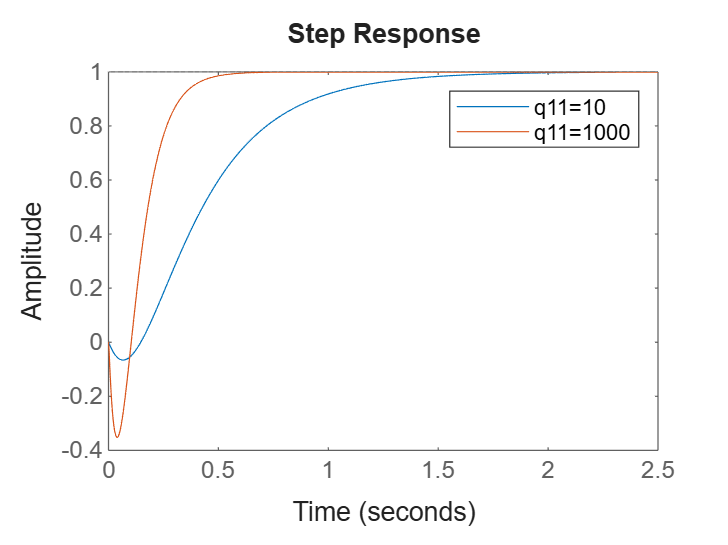


step(GCL1);hold on
step(GCL2);
legend('q11=10','q11=1000')